# Save Kilosort motion traces from rez.mat to MTracerTrace files

## Specify paths

% Motion correction folder
mcDir = "D:\preproc\mc_workspace\NP134_B2_g0_imec0";

% Path to the rez.mat file
rezPath = fullfile(mcDir, "rez.mat");

% The folder to save MTracerTrace files
[~, probeId] = fileparts(mcDir);
traceDir = fullfile(mcDir, "MTracer_"+probeId+"_ks-auto");

## Load rez.mat

load(rezPath);

## Visualize traces from Kilosort auto motion correction

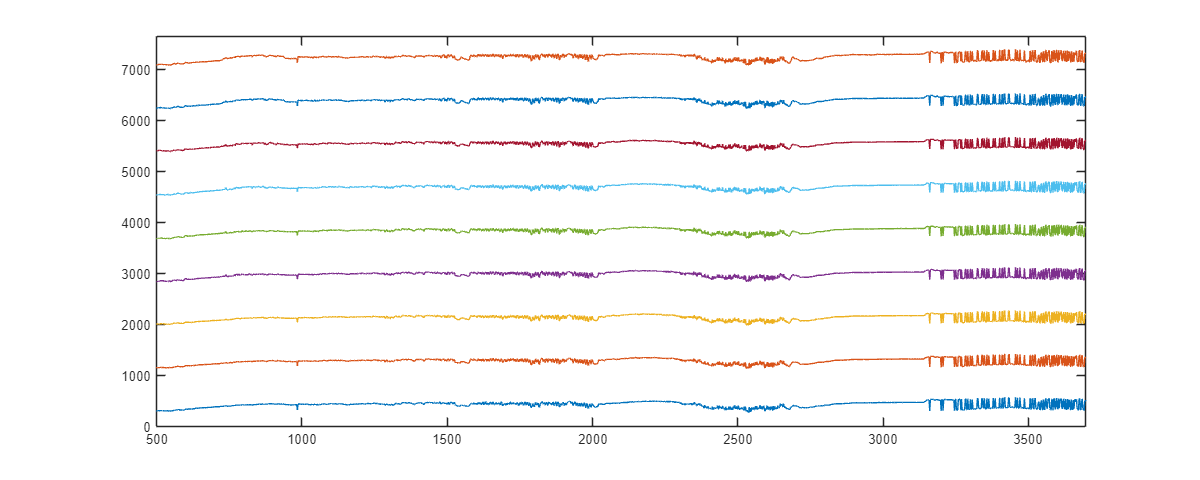

ops = rez.ops;
tLims = [ops.tstart, ops.tstart+ops.sampsToRead] / ops.fs;
yLims = [min(rez.ycoords), max(rez.ycoords)];

% st = rez.st0;
% t = (st(:,1) + ops.tstart) / ops.fs;
% y = st(:,2);
% a = st(:,3);

D = rez.dshift;
tD = tLims(1) : rez.ops.NT/rez.ops.fs : tLims(2);
tD = tD + rez.ops.NT/rez.ops.fs/2;
% tEdgesD = linspace(tLims(1), tLims(2), size(D,1)+1);
% tD = MMath.BinEdges2Centers(tEdgesD);
yEdgesD = linspace(yLims(1), yLims(2), size(D,2)+1);
yD = MMath.BinEdges2Centers(yEdgesD);

f = MPlot.Figure(2626); clf
f.Position(3:4) = [1200 480];
plot(tD(:), yD-D);
xlim(tLims);
ylim(yLims);

## Select a subset of traces

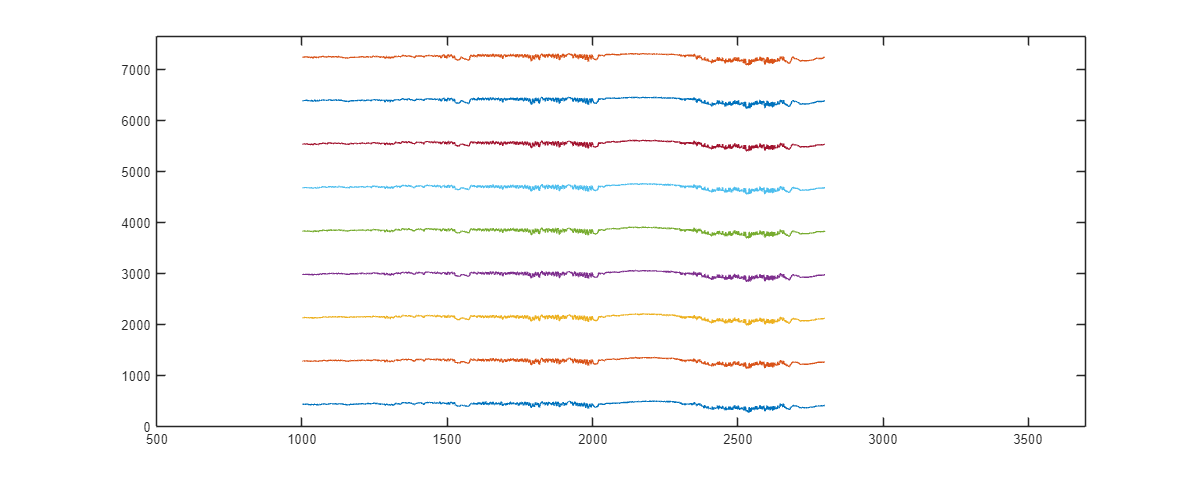

tMask = tD > 1000 & tD < 2800;
tSub = tD(tMask)';
ySub = yD - D(tMask,:);

f = MPlot.Figure(2626); clf
f.Position(3:4) = [1200 480];
plot(tSub, ySub);
xlim(tLims);
ylim(yLims);

## Save the traces as MTracerTrace files

if ~isfolder(traceDir)
    mkdir(traceDir)
end

nTraces = size(D, 2);
for i = 1 : nTraces
    dataTb = table;
    dataTb.t = tSub;
    dataTb.y = ySub(:,i);
    dataTb.isDone(:) = true;
    
    traceName = sprintf("MTracerTrace_%s_%i-%is_%ium.mat", probeId, round(tSub(1)), round(tSub(end)), round(median(ySub(:,i))));
    save(fullfile(traceDir, traceName), "dataTb");
    fprintf("Saved %s\n", traceName);
end

Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_448um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_1301um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_2155um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_3002um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_3852um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_4702um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_5555um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_6404um.mat
Saved MTracerTrace_NP134_B2_g0_imec0_1002-2799s_7254um.mat
